# Демодуляция. Часть 2.

# Double Sideband Transmitted Carrier 

# (AM-DSB-TC)

**Для запуска скриптов необходимо корневую папку репозитория сделать рабочей папкой Matlab!**

### 1. Некогерентная демодуляция с помощью детектора огибающей

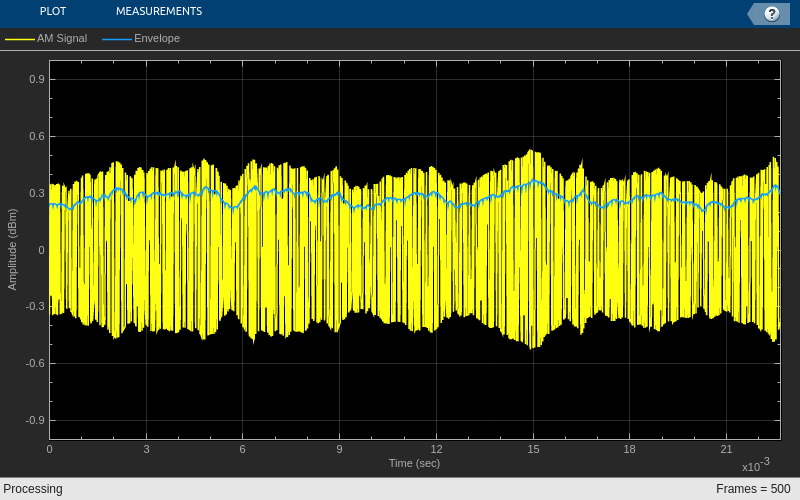

clc; clear; close all;
addpath('matlab/DSB_TC');

SignalFrameSize = 10000;  % количество отсчетов Ам-сигнала, получаемых за один раз
FramesNumber = 500;       % число обрабатываемых пачек данных
AudioAmp = 3;             % коэффициент усиления аудиосигнала
RateRatio = 10;           % коэффициент увеличения частоты дискретизации

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_DSB_TC.wav', ...
    'SamplesPerFrame',SignalFrameSize...
    );

% дополнительные расчеты
SignalFs = AudioReader.SampleRate;              % получаем частоту дискретизации модулированного сигнала
AudioFs = SignalFs / RateRatio;                 % частота дискретизации аудиосообщения

% рассчет коэффициентов фильтра нижних частот
H = Audio_Lowpass_FIR_Coeff();

% создание объекта для фильтрации
LowpassFIR = dsp.FIRFilter(H.Numerator);

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'YLimits', [-1, 1], ...
    'XLabel', 'Time (sec)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'AM Signal', 'Envelope'}, ...
    'SampleIncrement', 1/SignalFs ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов АМ-сигнала и выделение синфазного канала
    AmSignal = AudioReader();
    AmSignal = AmSignal(:,1);

    % вычисляем абсолютное значение отсчетов
    AbsAmSignal = abs(AmSignal);

    % фильтрация сигнала
    BasebandSignal = LowpassFIR(AbsAmSignal);

    % понижение частоты дискретизации
    Message = [Message; AudioAmp * DownSampler(BasebandSignal)];

    % вывод результатов на график
    Plotter([AmSignal BasebandSignal])

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

% проигрывание полученного сообщения
sound(Message, AudioFs);

В файле *DSB_TC_Receiver_Part_3_1.slx* представлена Simulink модель некогерентного демодулятора, который ранее был реализован ввиде скрипта. 

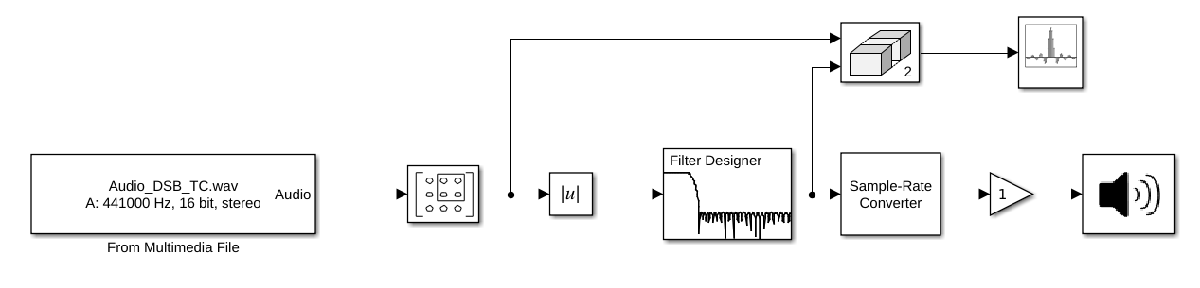 

### 2. Некогерентная демодуляция при квадратурном приеме

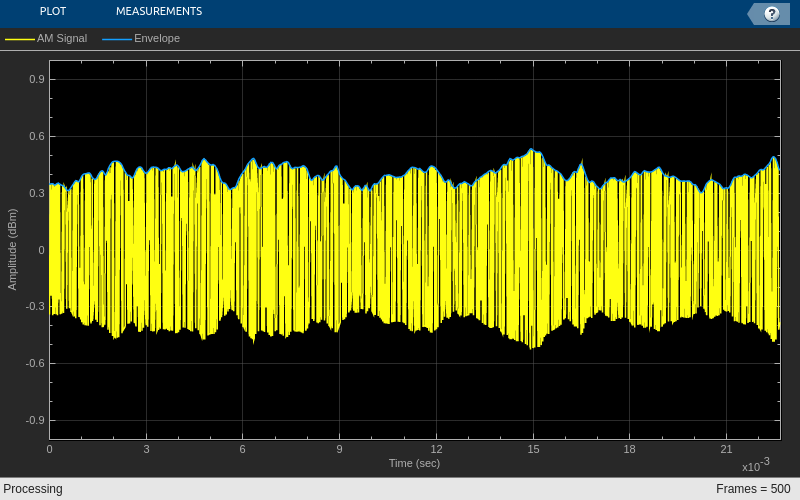

clc; clear; close all;

SignalFrameSize = 10000;  % количество отсчетов Ам-сигнала, получаемых за один раз
FramesNumber = 500;       % число обрабатываемых пачек данных
AudioAmp = 1;             % коэффициент усиления аудиосигнала
RateRatio = 10;           % коэффициент увеличения частоты дискретизации

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_DSB_TC.wav', ...
    'SamplesPerFrame',SignalFrameSize...
    );

% дополнительные расчеты
SignalFs = AudioReader.SampleRate;              % получаем частоту дискретизации модулированного сигнала
AudioFs = SignalFs / RateRatio;                 % частота дискретизации аудиосообщения

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'YLimits', [-1, 1], ...
    'XLabel', 'Time (sec)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'AM Signal', 'Envelope'}, ...
    'SampleIncrement', 1/SignalFs ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов АМ-сигнала и формирование комплексного сигнала
    AmSignal = AudioReader();
    AmSignal = AmSignal(:,1) + 1j*AmSignal(:,2);

    % вычисление амплитуды сигнала
    AbsAmSignal = abs(AmSignal);

    % понижение частоты дискретизации
    Message = [Message; AudioAmp*DownSampler(AbsAmSignal)];

    % вывод результатов на график
    Plotter([real(AmSignal) AbsAmSignal])

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

% проигрывание полученного сообщения
sound(Message, AudioFs);

В файле *DSB_TC_Receiver_Part_3_2.slx* представлена Simulink модель когерентного демодулятора в квадратурном случае. 

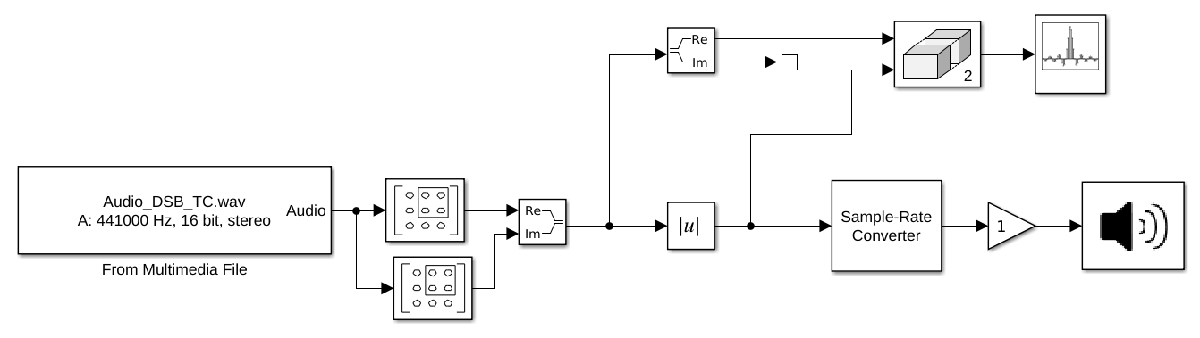

### Литература:

- B. P. Lathi Modern Digital and Analog Communication Systems

- R. Stewart, K. Barlee, D. Atkinson, L. Crockett Software Defined Radio using MATLAB® & Simulink and the RTL-SDR